# Paper2 Fig4

## Setting up WS

CurrentFolder = pwd

CurrentFolder = '/home/lai-sang/Documents/GitHub/NYU-Vision-2Drive'

addpath(CurrentFolder)
addpath([CurrentFolder '/Utils'])
addpath([CurrentFolder '/Data'])
DataFolder = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/Paper2PlotingData/']; % V1D2
DataFolder1 = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/GlobConv/']; % V1D2
DataFolder2 = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/Paper2PlotingData/Typical_trajs/']; % V1D2

addpath(DataFolder2)
addpath(DataFolder1)
addpath(DataFolder)
addpath([CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/'])

FigurePaperPath = [CurrentFolder '/Paper2Figs/']; % V1D2

### B1. Load LDE computations and do Fr distributions

Should rerun Sect 1 after in case loaded file contain any paths.

DataPoint = 'V4D2'; %'V4D1'; 'V5D1'
load(sprintf("AllMFPixPara_Paper2TuneFig1%s.mat",DataPoint))
CurrentFolder = pwd;
DataFolder = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/']; % V1D2


close all

## 2. Set up initial conditions

N_HCOut = 4; NPixX = 10; NPixY = 10;
IniNum = 3;
IniDespt = cell(IniNum,1);
LDEIniAll = cell(IniNum,1);


3 Inis. 1: E high/low

IniDespt{1} = 'f^E tuned up/down';
SaveExt{1} = 'fEUpDown';
ICData1 = load('LDETracesV4D2_NewSmear_ang22.5.mat');
LDEIniAll{1} = ICData1.LDEEquv;

HighE = 1.6; LowE = 0.6;
SHCs = reshape(LDEIniAll{1}.S,N_HCOut*NPixY,N_HCOut*NPixX);
SHCs(:,1:2*NPixX) = SHCs(:,1:2*NPixX)*HighE;
SHCs(:,2*NPixX+1:end) = SHCs(:,2*NPixX+1:end)*LowE;
LDEIniAll{1}.S = reshape(SHCs,N_HCOut*NPixY*N_HCOut*NPixX,1);

CHCs = reshape(LDEIniAll{1}.C,N_HCOut*NPixY,N_HCOut*NPixX);
CHCs(:,1:2*NPixX) = CHCs(:,1:2*NPixX)*HighE;
CHCs(:,2*NPixX+1:end) = CHCs(:,2*NPixX+1:end)*LowE;
LDEIniAll{1}.C = reshape(CHCs,N_HCOut*NPixY*N_HCOut*NPixX,1);

10 Inis. 2: HCwise random perturbation

IniDespt{2} = 'HCwise random';
SaveExt{2} = 'HCRandom';
ICData2 = load('LDETracesV4D2_NewSmear_ang0.0.mat');
LDEIniAll{2} = ICData2.LDEEquv;

SHCs = reshape(LDEIniAll{2}.S,N_HCOut*NPixY,N_HCOut*NPixX);
CHCs = reshape(LDEIniAll{2}.C,N_HCOut*NPixY,N_HCOut*NPixX);
IHCs = reshape(LDEIniAll{2}.I,N_HCOut*NPixY,N_HCOut*NPixX);
% get a random matrix for HCwise perturbation
%Perc = 0.6;
RandomRot = randi(5,4)-1; % 0-3 for rotation, 4 for bg
% assign the perturbations
for HCx = 1:N_HCOut
    for HCy = 1:N_HCOut
        if RandomRot(HCy,HCx)<4
            SHCs((HCy-1)*NPixY+1:HCy*NPixY, (HCx-1)*NPixX+1:HCx*NPixX) = ...
                rot90(SHCs((HCy-1)*NPixY+1:HCy*NPixY, (HCx-1)*NPixX+1:HCx*NPixX), RandomRot(HCy,HCx));
            CHCs((HCy-1)*NPixY+1:HCy*NPixY, (HCx-1)*NPixX+1:HCx*NPixX) = ...
                rot90(CHCs((HCy-1)*NPixY+1:HCy*NPixY, (HCx-1)*NPixX+1:HCx*NPixX), RandomRot(HCy,HCx));
            IHCs((HCy-1)*NPixY+1:HCy*NPixY, (HCx-1)*NPixX+1:HCx*NPixX) = ...
                rot90(IHCs((HCy-1)*NPixY+1:HCy*NPixY, (HCx-1)*NPixX+1:HCx*NPixX), RandomRot(HCy,HCx));
        else
            SHCs((HCy-1)*NPixY+1:HCy*NPixY, (HCx-1)*NPixX+1:HCx*NPixX) = 2.5;
            CHCs((HCy-1)*NPixY+1:HCy*NPixY, (HCx-1)*NPixX+1:HCx*NPixX) = 8;
            IHCs((HCy-1)*NPixY+1:HCy*NPixY, (HCx-1)*NPixX+1:HCx*NPixX) = 16;
        end
    end
end

LDEIniAll{2}.S = reshape(SHCs,N_HCOut*NPixY*N_HCOut*NPixX,1);
LDEIniAll{2}.C = reshape(CHCs,N_HCOut*NPixY*N_HCOut*NPixX,1);
LDEIniAll{2}.I = reshape(IHCs,N_HCOut*NPixY*N_HCOut*NPixX,1);

10 Inis. 3: Bright spot

IniDespt{3} = 'A bright Spot';
SaveExt{3} = 'BrightSpot';
SHCs = zeros(N_HCOut*NPixY,N_HCOut*NPixX);
CHCs = zeros(N_HCOut*NPixY,N_HCOut*NPixX);
IHCs = zeros(N_HCOut*NPixY,N_HCOut*NPixX);

% get the HCwise rate matrix ready
SHCr = [...
    10 10 10 3
    10 40 10 3
    10 10 10 3
    3  3  3  3];
CHCr = [...
    25 25  25 10
    25 100 25 10
    25 25  25 10
    10 10  10 10];
IHCr = [...
    80 80  80 20
    80 160 80 20
    80 80  80 20
    20 20  20 20];
% assign the HCwise rates
for HCx = 1:N_HCOut
    for HCy = 1:N_HCOut
        SHCs((HCy-1)*NPixY+1:HCy*NPixY, (HCx-1)*NPixX+1:HCx*NPixX) = SHCr(HCy,HCx);
        CHCs((HCy-1)*NPixY+1:HCy*NPixY, (HCx-1)*NPixX+1:HCx*NPixX) = CHCr(HCy,HCx);
        IHCs((HCy-1)*NPixY+1:HCy*NPixY, (HCx-1)*NPixX+1:HCx*NPixX) = IHCr(HCy,HCx);
    end
end

LDEIniAll{3}.S = reshape(SHCs,N_HCOut*NPixY*N_HCOut*NPixX,1);
LDEIniAll{3}.C = reshape(CHCs,N_HCOut*NPixY*N_HCOut*NPixX,1);
LDEIniAll{3}.I = reshape(IHCs,N_HCOut*NPixY*N_HCOut*NPixX,1);

Hyperparameters of iterations

p = 0.33; % 1-p for the original input
EpocTest = 300;

LDEEpoOutAll = cell(IniNum,1);
FuncUseAll = cell(IniNum,1);
L2Diff_OneStepAll = zeros(IniNum,EpocTest+1);
DiffVecAll = zeros(IniNum,EpocTest+1,NPixY*NPixX*3);


first get basic function information

AngleList = {'0.0','7.5','15.0','22.5'};

BgFlagAll = logical([0,0,1]);
AngleInptAll = [60 0 0]; % has to be multiples of 7.5
    N_HCOut = 4; PixNumOut = N_HCOut^2*NPixX*NPixY;

## 2. Set up LDE firing rate functions

for TestInd = 1:length(LDEIniAll)

Choose from the list, but input can take everything between 0-180

    BgFlag = BgFlagAll(TestInd);
    AngleInpt = AngleInptAll(TestInd);
    RotInd = floor(AngleInpt/45); % 0-3
    MirInd = mod(floor(AngleInpt/22.5),2); % 0: no mirror; 1: mirror
    switch MirInd % find the corresponding source
        case 0
            AngSource = mod(AngleInpt,45);
        case 1
            AngSource = mod(-AngleInpt,45);
    end
    
    % Use the source, decide which response function for angle should I use
    AngFuncCtgrCdid = 0:7.5:22.5;
    [~,AngFuncCtgr] = min(abs(AngFuncCtgrCdid - AngSource));
    
    AngPrint = AngleList{AngFuncCtgr};
    Angle = str2num(AngPrint); % can select from 0 7.5 15 22.5

load function depending on the Bgflag and angle

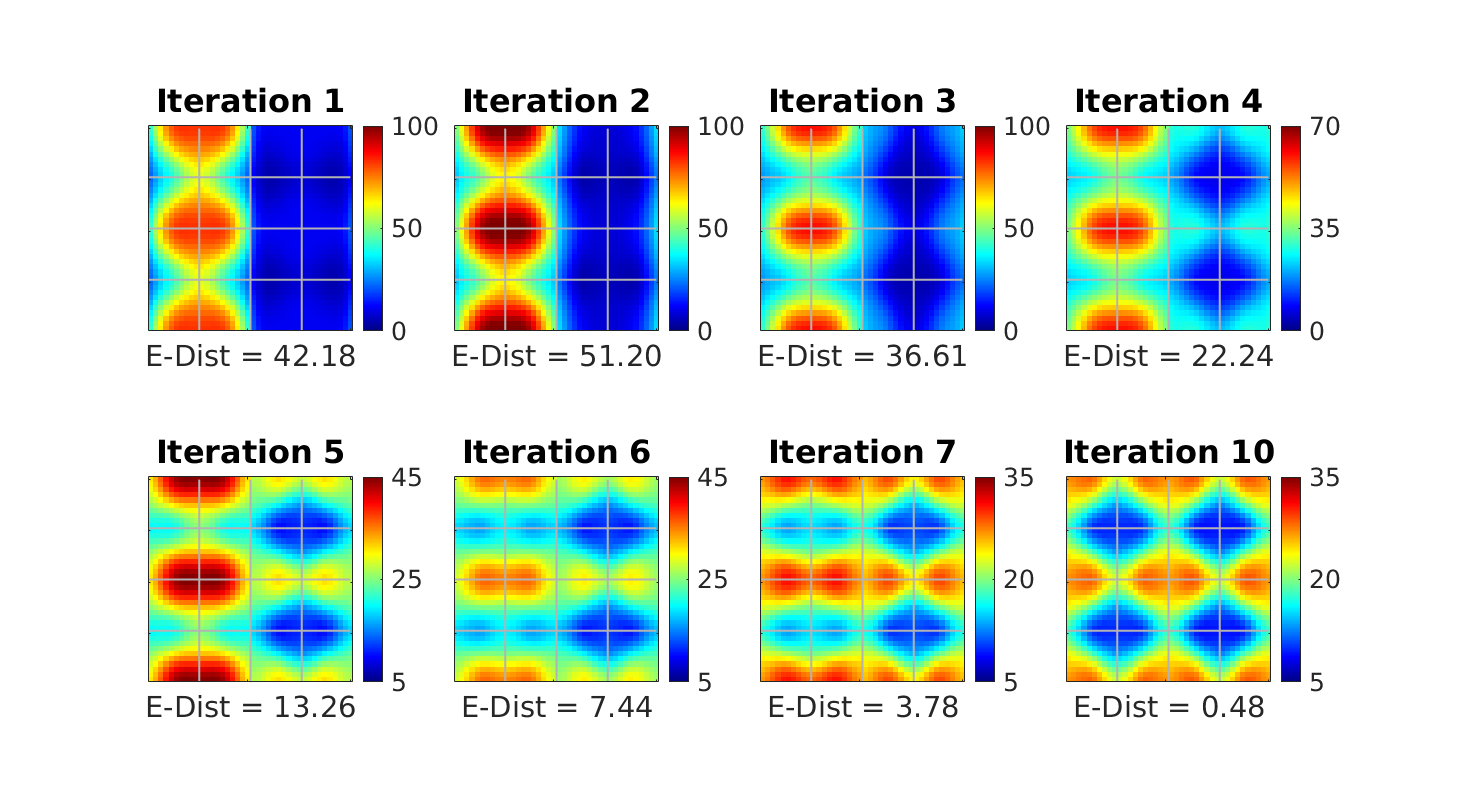

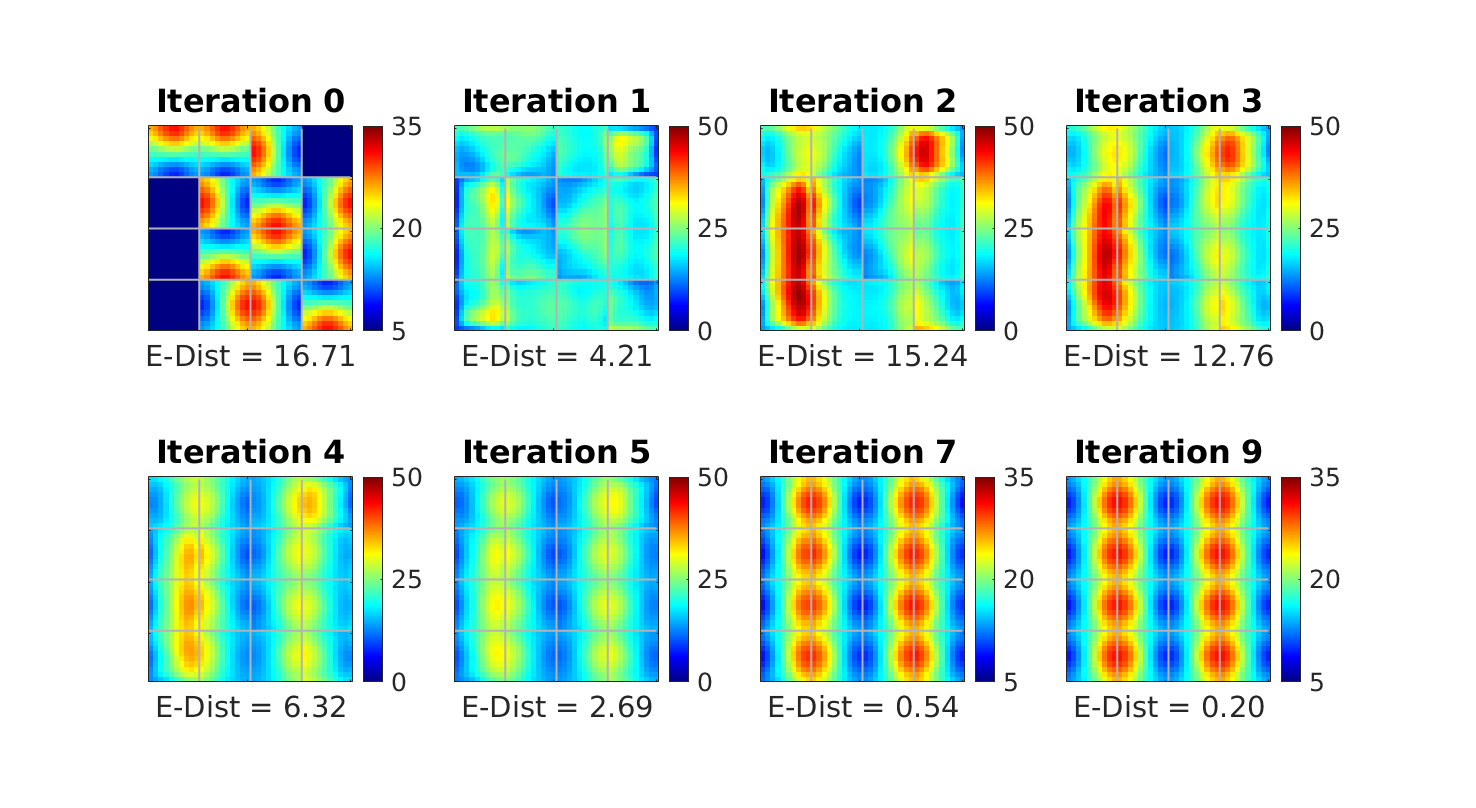

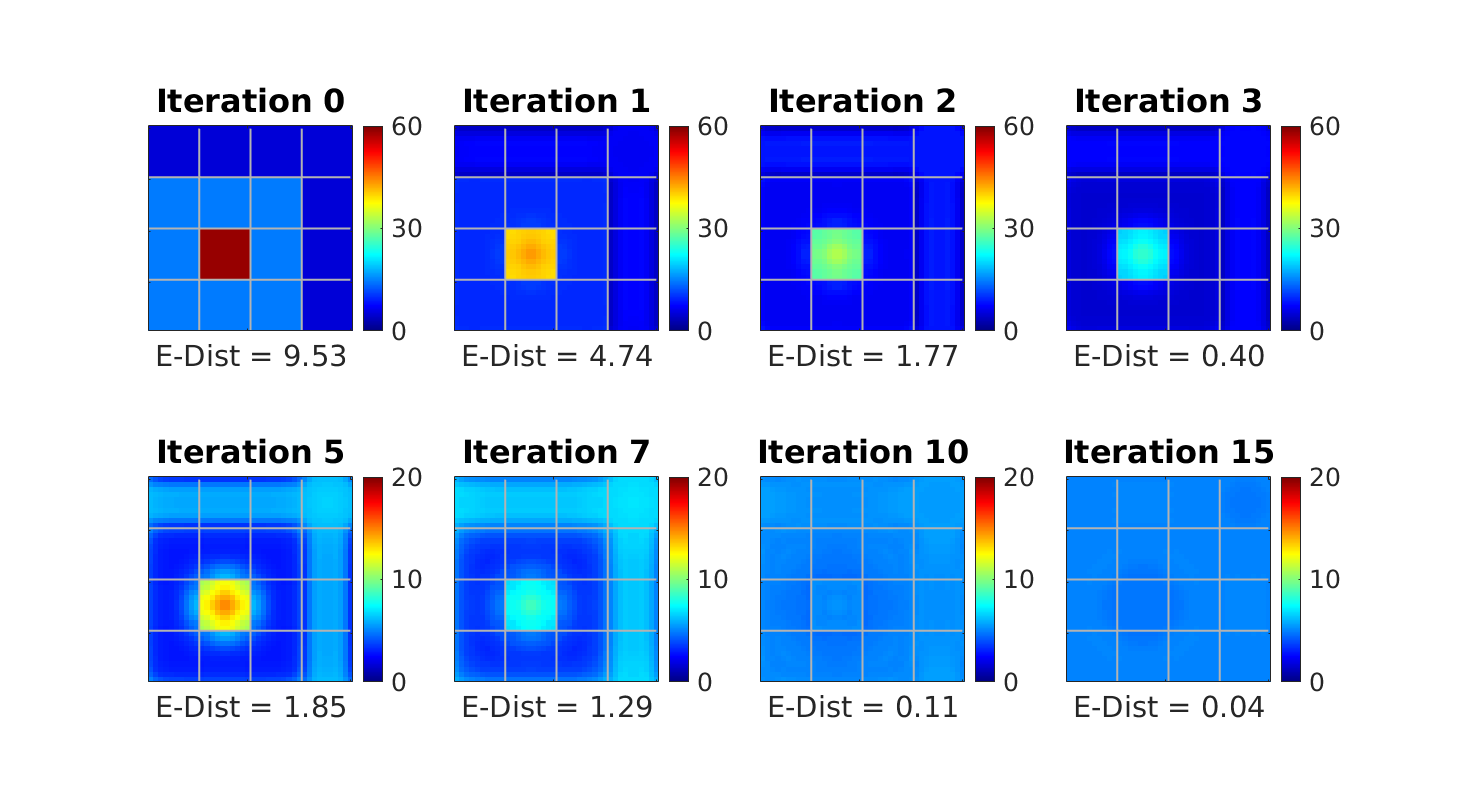

    if ~BgFlag
        DomList =  {'Small','Large','Larger','LARGER'};
        L4EmeshXAll = cell(size(DomList));
        L4ImeshYAll = cell(size(DomList));
        LDEFrfuncAll = cell(size(DomList));
        for DomInd = 1:length(DomList)
            FuncTemp = load(sprintf('Func16%sAng%s%s.mat',DataPoint,AngPrint,DomList{DomInd}),...
                'LDEFrfunc','L4EmeshX','L4ImeshY');
            L4EmeshXAll{DomInd} = FuncTemp.L4EmeshX;
            L4ImeshYAll{DomInd} = FuncTemp.L4ImeshY;
            LDEFrfuncAll{DomInd} = FuncTemp.LDEFrfunc;
        end
    else
        DomList =  {'Smaller','Small','Large'};
        
        Large = load(sprintf('FuncBG_%s_SM10_5.mat',DomList{3}),'LDEFrfunc','L4EmeshX','L4ImeshY');
        Small = load(sprintf('FuncBG_%s_SM10_5.mat',DomList{2}),'LDEFrfunc','L4EmeshX','L4ImeshY');
        Smaller = load(sprintf('FuncBG_%s_SM15_5.mat',DomList{1}),'LDEFrfunc','L4EmeshX','L4ImeshY');
        
        Cellctgr = fieldnames(Large.LDEFrfunc);
        
        LDEFrfuncLarge = Large.LDEFrfunc;
        LDEFrfuncSmall = Small.LDEFrfunc;
        LDEFrfuncSmaller = Smaller.LDEFrfunc;
        for CellInd = 1:length(Cellctgr)
            FN = Cellctgr{CellInd};
            LDEFrfuncLargeUse.(FN) = cell(length(AngleList));
            LDEFrfuncSmallUse.(FN) = cell(length(AngleList));
            LDEFrfuncSmallerUse.(FN) = cell(length(AngleList));
            for cg1 = 1:length(AngleList)
                for cg2 = 1:length(AngleList)
                    LDEFrfuncLargeUse.(FN){cg1, cg2} = LDEFrfuncLarge.(FN);
                    LDEFrfuncSmallUse.(FN){cg1, cg2} = LDEFrfuncSmall.(FN);
                    LDEFrfuncSmallerUse.(FN){cg1, cg2} = LDEFrfuncSmaller.(FN);
                end
            end
        end
        LDEFrfuncLarge = LDEFrfuncLargeUse;
        LDEFrfuncSmall = LDEFrfuncSmallerUse;
        LDEFrfuncSmaller = LDEFrfuncSmallerUse;
        
        L4EmeshXAll = {Smaller.L4EmeshX, Small.L4EmeshX, Large.L4EmeshX};
        L4ImeshYAll = {Smaller.L4ImeshY, Small.L4ImeshY, Large.L4ImeshY};
        LDEFrfuncAll = {LDEFrfuncSmaller, LDEFrfuncSmall, LDEFrfuncLarge};
        
        %     L4ESmallerUB = max(L4EmeshXSmaller,[],'all');
        %     L4ESmallUB = max(L4EmeshXSmall,[],'all');
    end

## 4. Iteration 

New: Need to extend all these to arbitrary HC numbers!

%    N_HCOut = 4; PixNumOut = N_HCOut^2*NPixX*NPixY;
    LGNlist = 4; L6list = 4;

LGN and L6 are blurred 

    FigOn = false;
    L6smear = n_S_HC*0.34; LGNsmear = n_S_HC*0.2;
    TruncL6 = 1.25; TruncLGN = 1;
    L6SFilt_Grating = SpatialGaussianFilt_my(OD_SMap,...
        N_HC,n_S_HC,L6smear,TruncL6,FigOn);
    LGNFilt_Grating = SpatialGaussianFilt_my(OD_SMap,...
        N_HC,n_S_HC,LGNsmear,TruncLGN,FigOn);
    

NewTitle = 1×3 cell array
    {'Stress test A'}    {'Stress test B'}    {'Stress test C'}


    PixL6Ctgr = LGNIndSpat(L6SFilt_Grating,1:4,NnSPixel,N_HC,N_HCOut,NPixX,NPixY);
    PixLGNCtgr = LGNIndSpat(LGNFilt_Grating,1:4,NnSPixel,N_HC,N_HCOut,NPixX,NPixY);

However, the Ctgr for pixels needs to be rotated/flipped to represent the actual gratings

    MirInd = logical(MirInd);
    for Ctgr = 1:4
        PixL6Ctgr(:,Ctgr) = HCRot(PixL6Ctgr(:,Ctgr),RotInd,N_HCOut,NPixX,NPixY,MirInd);
        PixLGNCtgr(:,Ctgr) = HCRot(PixLGNCtgr(:,Ctgr),RotInd,N_HCOut,NPixX,NPixY,MirInd);
    end
    
    PixInptCtgrUse  = zeros(PixNumOut,LGNlist,L6list);
    for PixInd = 1:PixNumOut
        PixInptCtgrUse(PixInd,:,:) = PixLGNCtgr(PixInd,:)' *PixL6Ctgr(PixInd,:);% by multiplying both indexes
    end

Get pixelwise connectivities

    C_SS_mean = AveSpatKer(C_SS_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
    C_CS_mean = AveSpatKer(C_CS_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
    C_IS_mean = AveSpatKer(C_IS_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
    C_SC_mean = AveSpatKer(C_SC_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
    C_CC_mean = AveSpatKer(C_CC_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
    C_IC_mean = AveSpatKer(C_IC_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
    C_SI_mean = AveSpatKer(C_SI_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
    C_CI_mean = AveSpatKer(C_CI_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
    C_II_mean = AveSpatKer(C_II_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);

Firing rate suppresion

    %     EKp.Thrsld = 50; EKp.Highist = [200,150]; EKp.HardBound = 200; EKp.Slope = 0;
    %
    %     IKp.Thrsld = 70; IKp.Highist = [100,95];  IKp.HardBound = 120; IKp.Slope = 1;

start iteration

    %LDEEquv = zeros(3*N_HCOut^2*NPixY*NPixX,IniNum);
    tic
    
    IniTest = LDEIniAll{TestInd};

            use the new combined domain function

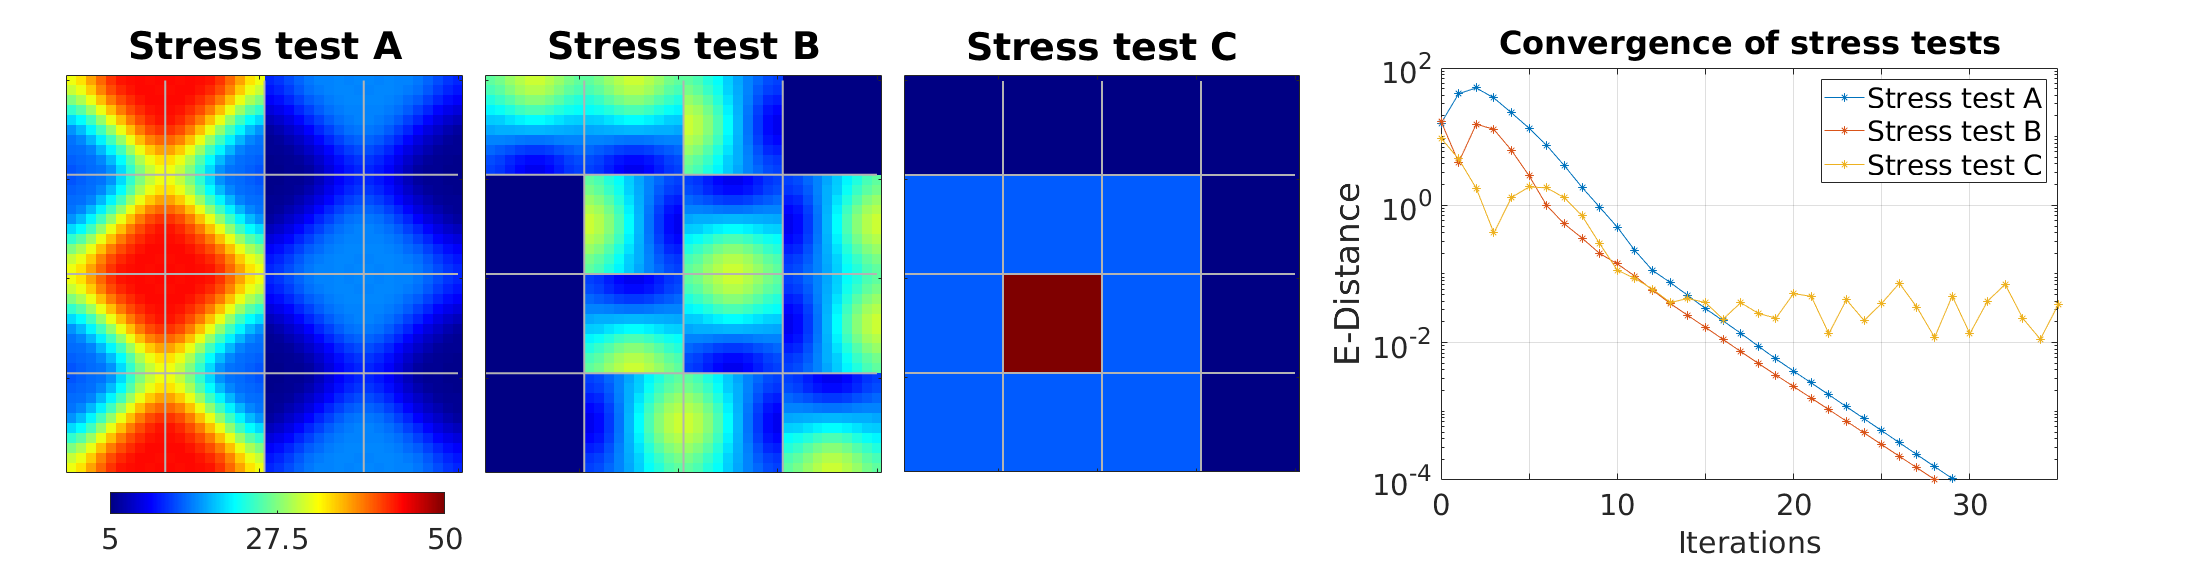

    [LDEEpoOutAll{TestInd},~,~,~,~,FuncUseAll{TestInd}] = ...
        LDEIteration_16FuncMain_CombDom(...
        PixInptCtgrUse,IniTest,p,EpocTest,...
        C_SS_mean,C_CS_mean,C_IS_mean,...
        C_SC_mean,C_CC_mean,C_IC_mean,...
        C_SI_mean,C_CI_mean,C_II_mean,...
        L4EmeshXAll,L4ImeshYAll,LDEFrfuncAll,...
        N_HCOut,NPixX,NPixY,false,'xn')  ;

    LDEEquv = LDEEpoOutAll{TestInd}{end};

    Below was HCwise diffs. Discarded

    for EpcInd = 1:length(LDEEpoOutAll{TestInd})
        LDEPertRslt = LDEEpoOutAll{TestInd}{EpcInd};
        SDiff = LDEPertRslt.S - LDEEquv.S;
        SDiffHC = reshape(SDiff,N_HCOut*NPixY,N_HCOut*NPixX);
        SDiff = reshape(SDiffHC(1:NPixY,1:NPixX),NPixY*NPixX,1);
        CDiff = LDEPertRslt.C - LDEEquv.C;
        CDiffHC = reshape(CDiff,N_HCOut*NPixY,N_HCOut*NPixX);
        CDiff = reshape(CDiffHC(1:NPixY,1:NPixX),NPixY*NPixX,1);
        IDiff = LDEPertRslt.I - LDEEquv.I;
        IDiffHC = reshape(IDiff,N_HCOut*NPixY,N_HCOut*NPixX);
        IDiff = reshape(IDiffHC(1:NPixY,1:NPixX),NPixY*NPixX,1);
        
        L2Diff_OneStepAll(TestInd,EpcInd) = ...
            sqrt(sum((SDiff*(1-CplxR)+CDiff*CplxR).^2,'all'));%sqrt(sum([SDiff;CDiff;IDiff].^2));
        DiffVecAll(TestInd,EpcInd,:) = [SDiff;CDiff;IDiff];
    end
    toc
end
save([DataFolder 'Fig4MainABC_data.mat'],'LDEEpoOutAll','L2Diff_OneStepAll','DiffVecAll')

investigate BG trajs

load([DataFolder 'Fig4MainABC_data.mat'],'LDEEpoOutAll','L2Diff_OneStepAll','DiffVecAll')
for TestUse = 1:3
    AngleInpt = AngleInptAll(TestUse);
    Fig4s = ...
        figure("Name",sprintf('%.1f',AngleInpt),'units','normalized','outerposition',[0,0,0.3,0.44]);
    EpocList = ...
        [2:8, 11;
         1:6, 8, 10;
         1:4,6, 8, 11, 16]; % for angles
    Panel1 = 2; Panel2 = 4;%length(EpocList);
    ha = tight_subplot(Panel1,Panel2,[.03 .03],[.08 .08],[.10 .10]);
    DispTest = TestUse;

Use corresponding trajectories and 

    LDEEpoOut = LDEEpoOutAll{DispTest};
    CaxeAll{1} = [repmat([0 100],3,1);[0 70];repmat([5 45],2,1);repmat([5 35],2,1)];
    CaxeAll{2} = [repmat([5 35],1,1);repmat([0 50],5,1);repmat([5 35],3,1);];
    CaxeAll{3} = [repmat([0 60],1,1);repmat([0 60],3,1);repmat([0 20],4,1)];
    %Caxe = [repmat([0 50],1,1);repmat([0 200],3,1);repmat([0 50],2,1);repmat([0 37],2,1)];
    %Caxe = [repmat([0 60],4,1);repmat([0 35],4,1)];
    Caxe = CaxeAll{DispTest};
    for EpocInd = 1:length(EpocList(DispTest,:))
        Epoc = EpocList(DispTest,EpocInd);
        %subplot(2,6,EpocInd+6*(ICInd-1))
        axes(ha(EpocInd));
        LDEPlot = LDEEpoOut{Epoc};
        ShowField(...
            ...%LDEPlot.I,...
            LDEPlot.S*(1-CplxR)+LDEPlot.C*CplxR,...
            1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY,...
            sprintf('Iteration %d',Epoc-1), Caxe(EpocInd,:)) % last input may catgorized cbar: ,, [5 60]
        set(gca,'fontsize',22)
        set(gca,'YTickLabel',[]);
        set(gca,'XTickLabel',[]);
        xlabel(sprintf('E-Dist = %.2f',...
               L2Diff_OneStepAll(DispTest,Epoc)/(sqrt(NPixY*NPixX))),... %N_HCOut^2*
              'Interpreter',"tex",'fontsize',22)
        % set colorbars
        colorbar off
        a = min(Caxe(EpocInd,:)); b = max(Caxe(EpocInd,:));
        cbar = colorbar;     set(cbar,'FontSize',19,'XTick',[a,(a+b)/2,b])                               
    end

Save figures

    FigName1 = sprintf('Figure4_%s_NewSmear',SaveExt{DispTest});
    savefig(Fig4s,[FigurePaperPath FigName1 '.fig']);
    

Print Figs

    Fig4s.PaperUnits = 'centimeters';
    Fig4s.PaperSize = [36,28];
    Fig4s.PaperOrientation = "landscape";
    exportgraphics(Fig4s,[FigurePaperPath FigName1 '.pdf'],'Resolution',300)
end

## 5. Fig4

plot 3 inis

Fig4FinalDraft = figure('Name','Fig4FinalDraft','units','normalized','outerposition',[0,0,0.45,0.31]);
Panel1 = 1; Panel2 = 5;%length(EpocList);
ha = tight_subplot(Panel1,Panel2,[.05 .01],[.15 .12],[.03 .03]);
set(ha(4),'visible','off')
set(ha(5),'visible','off')
Caxe = [5 50]; a = min(Caxe); b = max(Caxe);
PixNumOut = N_HCOut^2*NPixX*NPixY;

NewTitle = {'Stress test A','Stress test B','Stress test C'}
for testId = 1:length(LDEIniAll)
    axes(ha(testId));
    LDEPlot = LDEEpoOutAll{testId}{1};
    ShowField(...
        ...%LDEPlot.I,...
        LDEPlot.S*(1-CplxR)+LDEPlot.C*CplxR,...
        1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY,...
        NewTitle{testId}, Caxe) % last input may catgorized cbar: ,, [5 60]
    set(gca,'fontsize',26)
    set(gca,'YTickLabel',[]);
    set(gca,'XTickLabel',[]);
    colorbar off
    if testId == 1
        Pos1 = get(gca,'Position');
        cbr1 = colorbar('SouthOutside');
        cbr1.Position = [Pos1(1)+0.02  Pos1(2)-0.06 Pos1(3)  0.04];
        caxis(Caxe)
        set(cbr1,'YTick',[a,(a+b)/2,b],'FontSize',22)
    end
    if testId == 3
        Pos3 = get(gca,'Position');
    end
    
end

ax4 = axes('Position',[Pos3(1)+Pos3(3)+0.09  Pos3(2)  0.28  Pos3(4)],'Box','on');
set(gca, 'YScale', 'log')
set(gca,'fontsize',22)
xlabel('Iterations','FontSize',23); ylabel('E-Distance','Interpreter',"tex",'FontSize',26)
title('Convergence of stress tests','fontsize',26)
ylim([1e-4 1e2])
xlim([0 35])

Fig4Legend{1} = '$$f^E$$ tuned up/down $$\rightarrow 60^\circ$$ response';
Fig4Legend{2} = 'HCwise random $$\rightarrow 0^\circ$$ response';
Fig4Legend{3} = 'A bright spot $$\rightarrow$$ background';

for TestInd = 1:length(LDEIniAll)
    hold on
    plot(0:length(L2Diff_OneStepAll(TestInd,:))-1, L2Diff_OneStepAll(TestInd,:)/(sqrt(NPixY*NPixX)),...
        'DisplayName',NewTitle{TestInd},'Marker','*') % N_HCOut^2*
end
hl = legend('show');
set(hl,'FontSize',21)
%set(hl, 'Interpreter','latex','fontsize',13)
% plot(51*ones(size(1:10:100)),1:10:100,'b','LineWidth',3,'HandleVisibility','off')
% plot(102*ones(size(1:10:100)),1:10:100,'b','LineWidth',3,'HandleVisibility','off')
grid on
set(ax4,'XTick', 0:5:40,'XTickLabel',{'0','', '10','','20','','30','','40'},...
    'YMinorGrid', 'off')

Save figures

FigName1 = sprintf('Figure4Draft');
savefig(Fig4FinalDraft,[FigurePaperPath FigName1 '.fig']);


Print Figs

Fig4FinalDraft.PaperUnits = 'centimeters';
Fig4FinalDraft.PaperSize = [3.2,7];
Fig4FinalDraft.PaperOrientation = "landscape";
exportgraphics(Fig4FinalDraft,[FigurePaperPath FigName1 '.pdf'],'Resolution',300)


Make an extra fig for epoc 1-8 anyway...

Fig4a = figure("Name",sprintf('%.1f',AngleInpt),'units','normalized','outerposition',[0,0,0.6,0.55]);%figure('Name','Fig3_EpocScan','units','normalized','outerposition',[-1,0,0.5,0.4]);

TestUse = 2;
LDEEpoOut = LDEEpoOutAll{TestUse};
Panel1 = 3; Panel2 = 4;%length(EpocList);
ha = tight_subplot(Panel1,Panel2,[.06 .06],[.08 .08],[.10 .10]);
%LDEEpoOut = LDEOutAll{1};
CaxeAll{1} = [repmat([0 120],5,1);repmat([0 40],8,1);];
%Caxe = [repmat([0 50],4,1);repmat([0 35],4,1)];
CaxeAll{2} = [repmat([0 60],8,1); repmat([0 180],8,1)];
CaxeAll{3} = [repmat([0 60],4,1); repmat([0 15],4,1); repmat([0 15],20,1)];
Caxe = CaxeAll{TestUse};
for Epoc = 2:13
    %subplot(2,6,EpocInd+6*(ICInd-1))
    LDEPlot = LDEEpoOut{Epoc};

    axes(ha(Epoc-1));
    ShowField(...
        LDEPlot.S*(1-CplxR)+LDEPlot.C*CplxR,...
        1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY,...
        sprintf('fE Iteration %d',Epoc-1), Caxe(Epoc,:)) % last input may catgorized cbar: ,, [5 60]
    set(gca,'fontsize',16)
    set(gca,'YTickLabel',[]);
    set(gca,'XTickLabel',[]);
    xlabel(sprintf('$$|x(%d) - x^*|_E = %.2f$$',...
        Epoc-1 , L2Diff_OneStepAll(TestUse,Epoc)/(sqrt(NPixX*NPixY))),...
        'Interpreter',"latex")

%     axes(ha(Epoc+8));
%     ShowField(...
%         LDEPlot.I,...
%         1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY,...
%         sprintf('fI Iteration %d',Epoc-1), Caxe(Epoc+8,:)) % last input may catgorized cbar: ,, [5 60]
%     set(gca,'fontsize',16)
%     set(gca,'YTickLabel',[]);
%     set(gca,'XTickLabel',[]);
end

save and print Fig3a

FigName2 = sprintf('Figure4aExp_%s_%.1fKI',SaveExt{DispTest},(IKp.Slope)^2);
savefig(Fig4a,[FigurePaperPath FigName2 '.fig']);


Print Figs

Fig4a.PaperUnits = 'centimeters';
Fig4a.PaperSize = [36,36];
Fig4a.PaperOrientation = "landscape";
exportgraphics(Fig4a,[FigurePaperPath FigName2 '.pdf'],'Resolution',300)

( L4E(F_s(L4E L4I), F_C(L4E L4I)), L4I(F_I(L4E L4I)) ) = (L4E L4I)

% % fS = Small.LDEFrfunc.S;
% % fC = Small.LDEFrfunc.C;
% % fI = Small.LDEFrfunc.C;
%
% L4E = zeros(length(LDEEpoOut),length(LDEIniAll));
% L4I = zeros(length(LDEEpoOut),length(LDEIniAll));
% fSAll = zeros(length(LDEEpoOut),length(LDEIniAll));
% fCAll = zeros(length(LDEEpoOut),length(LDEIniAll));
% fIAll = zeros(length(LDEEpoOut),length(LDEIniAll));
% for testInd = 1:length(LDEIniAll)
%     LDEEpoOut = LDEEpoOutAll{testInd};
%     for EpocInd = 1:length(LDEEpoOut)
%         LDEPlot = LDEEpoOut{EpocInd};
%         fS = mean(LDEPlot.S,'all');
%         fC = mean(LDEPlot.C,'all');
%         fI = mean(LDEPlot.I,'all');
%
%         L4SE = (N_SS*fS + N_SC*fC);
%         L4SI =  N_SI*fI ;
%         L4CE = (N_CS*fS + N_CC*fC);
%         L4CI =  N_CI*fI ;
%         L4IE = (N_IS*fS + N_IC*fC);
%         L4II =  N_II*fI ;
%
%         L4E(EpocInd,testInd) = L4SE + L4CE + L4IE;
%         L4I(EpocInd,testInd) = L4SI + L4CI + L4II;
%         fSAll(EpocInd,testInd) = fS;
%         fCAll(EpocInd,testInd) = fC;
%         fIAll(EpocInd,testInd) = fI;
%     end
% end
%
% hBG = cell(size(LDEIniAll));
% for testInd = 1:length(LDEIniAll)
%     hBG{testInd} = figure('units','normalized','outerposition',[-1,0,0.2,0.3]);
%     % plot(50:70,80*ones(size(50:70)),'r','LineWidth',5)
%     % plot(50:70,90*ones(size(50:70)),'r','LineWidth',5)
%     subplot 231
%     cAll = {'r','g','b'};
%     hold on
%     plot_dir(L4E(:,testInd), L4I(:,testInd), cAll{testInd});
%     hold on
%     MS = mesh(unique(Smaller.L4EmeshX), unique(Smaller.L4ImeshY),Smaller.LDEFrfunc.S,'FaceAlpha','0.4');
%     %MS = mesh(unique(Large.L4EmeshX), unique(Large.L4ImeshY),Large.LDEFrfunc.S,'FaceAlpha','0.4');
%
%     MS.FaceColor = 'flat';
%     MS.EdgeColor = 'none';
%     hold on
%     colorbar
%     xlabel('L4E'); ylabel('L4I')
%
%     title('S response')
%
%     subplot 232
%     hold on
%     plot_dir(fSAll(:,testInd)*(1-CplxR)+fCAll(:,testInd)*CplxR, ...
%         fIAll(:,testInd), cAll{testInd});
%     hold on
%     xlabel('fE'); ylabel('fI')
%
%
%     rangeStart = [150, 200, 250, 280];
%     for ranInd = 1:length(rangeStart)
%         subplot(2, 3, ranInd+2)
%         range = rangeStart(ranInd):300;
%         hold on
%         plot_dir(fSAll(range,testInd)*(1-CplxR)+fCAll(range,testInd)*CplxR, ...
%             fIAll(range,testInd), cAll{testInd});
%         hold on
%
%         xlabel('fE'); ylabel('fI')
%         title(sprintf('last %d iterations', length(range)))
%     end
% end
% % Norm = (L4E - Small.L4EmeshX).^2 + (L4I - Small.L4ImeshY).^2;
% %
% %
% %
% %
% % contour(Small.L4EmeshX,Small.L4ImeshY,Norm,5,'r',"ShowText",'on');
% for testInd = 1:length(LDEIniAll)
%     FigName1 = sprintf('Figure4BGTraj_%d',testInd);
%     savefig(hBG{testInd},[FigurePaperPath FigName1 '.fig']);
%
%     hBG{testInd}.PaperUnits = 'centimeters';
%     hBG{testInd}.PaperSize = [10,10];
%     hBG{testInd}.PaperOrientation = "landscape";
%     exportgraphics(hBG{testInd},[FigurePaperPath FigName1 '.pdf'],'Resolution',300)
% end
%
%